Here we want to find the acceptable torque for the servo and velocity for the beam.

Data coms from the pdf: "MS2N Synchronous Servomotors"

First the servo specs: 

Type: ***MS2N03-B0BYN-HMSH1-NNNNN-NN***

***3~PM-MOTOR***

***n(N) 6470 1/min***

***n(max) 9000 1/min***

***U(max) AC 600 V***

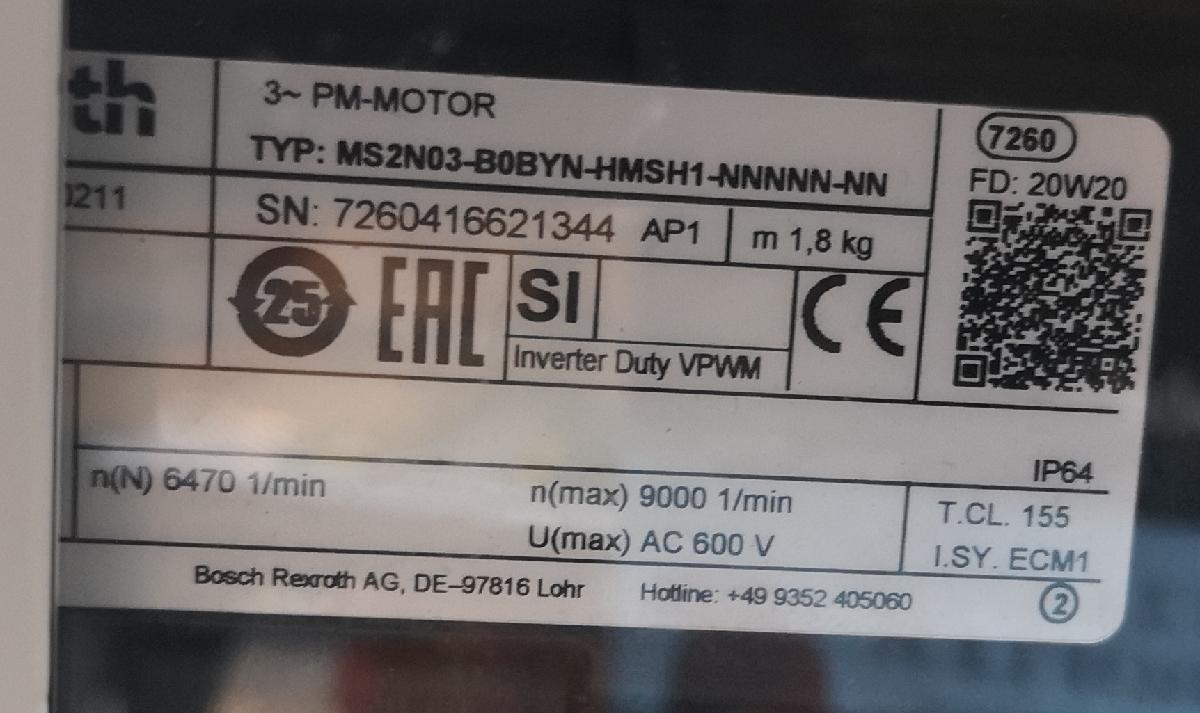

Beam with no ball center of mass Balanced:

***Only the beam:***

Mass properties of Sammenstilling V3.2-LAPTOP-44QB4H0M

     Configuration: Default

     Coordinate system: Coordinate System1

Mass = 0.40237903 kilograms

Volume = 0.00030401 cubic meters

Surface area = 0.19049638 square meters

Center of mass: ( meters )

	X = 0.00733656

	Y = -0.00497760

	Z = 0.04227204

Principal axes of inertia and principal moments of inertia: ( kilograms * square meters )

Taken at the center of mass.

	 Ix = ( 0.99996290, -0.00808711,  0.00296667)   	Px = 0.00026788

	 Iy = ( 0.00830504,  0.81368510, -0.58124658)   	Py = 0.03606421

	 Iz = ( 0.00228667,  0.58124965,  0.81372207)   	Pz = 0.03615710

Moments of inertia: ( kilograms * square meters )

Taken at the center of mass and aligned with the output coordinate system.

	Lxx = 0.00027053	Lxy = -0.00028960	Lxz = 0.00010602

	Lyx = -0.00028960	Lyy = 0.03609325	Lyz = -0.00004480

	Lzx = 0.00010602	Lzy = -0.00004480	Lzz = 0.03612540

Moments of inertia: ( kilograms * square meters )

Taken at the output coordinate system.

	Ixx = 0.00099952	Ixy = -0.00030430	Ixz = 0.00023081

	Iyx = -0.00030430	Iyy = 0.03683393	Iyz = -0.00012946

	Izx = 0.00023081	Izy = -0.00012946	Izz = 0.03615703

--------------------------------------------------------------------------------------------------------------

***With the ball on the tip:***

Mass properties of Sammenstilling V3.2-LAPTOP-44QB4H0M

     Configuration: Default

     Coordinate system: Coordinate System1

Mass = 0.40520721 kilograms

Volume = 0.00030665 cubic meters

Surface area = 0.20033258 square meters

Center of mass: ( meters )

	X = 0.00962272

	Y = -0.00488233

	Z = 0.04232563

Principal axes of inertia and principal moments of inertia: ( kilograms * square meters )

Taken at the center of mass.

	 Ix = ( 0.99996565, -0.00767245,  0.00313674)   	Px = 0.00026948

	 Iy = ( 0.00807443,  0.81612611, -0.57781742)   	Py = 0.03636670

	 Iz = ( 0.00187330,  0.57782290,  0.81616003)   	Pz = 0.03645922

Moments of inertia: ( kilograms * square meters )

Taken at the center of mass and aligned with the output coordinate system.

	Lxx = 0.00027196	Lxy = -0.00027704	Lxz = 0.00011308

	Lyx = -0.00027704	Lyy = 0.03639547	Lyz = -0.00004450

	Lzx = 0.00011308	Lzy = -0.00004450	Lzz = 0.03642798

Moments of inertia: ( kilograms * square meters )

Taken at the output coordinate system.

	Ixx = 0.00100753	Ixy = -0.00029608	Ixz = 0.00027812

	Iyx = -0.00029608	Iyy = 0.03715890	Iyz = -0.00012824

	Izx = 0.00027812	Izy = -0.00012824	Izz = 0.03647516

***Specifications for real beam used in the physical system:***

Mass properties of Sammenstilling V3.2-LAPTOP-44QB4H0M

     Configuration: Default

     Coordinate system: -- default --

Mass = 0.30555769 kilograms

Volume = 0.00028934 cubic meters

Surface area = 0.17884038 square meters

Center of mass: ( meters )

	X = 0.12748815

	Y = -0.00495633

	Z = 0.03996905

Principal axes of inertia and principal moments of inertia: ( kilograms * square meters )

Taken at the center of mass.

	 Ix = ( 0.99951750, -0.01678212,  0.02613662)   	Px = 0.00023352

	 Iy = ( 0.02707604,  0.88309313, -0.46841586)   	Py = 0.01772599

	 Iz = (-0.01522006,  0.46889752,  0.88312143)   	Pz = 0.01781718

Moments of inertia: ( kilograms * square meters )

Taken at the center of mass and aligned with the output coordinate system.

	Lxx = 0.00025042	Lxy = -0.00029277	Lxz = 0.00045820

	Lyx = -0.00029277	Lyy = 0.01774112	Lyz = -0.00004543

	Lzx = 0.00045820	Lzy = -0.00004543	Lzz = 0.01778516

Moments of inertia: ( kilograms * square meters )

Taken at the output coordinate system.

	Ixx = 0.00074606	Ixy = -0.00048584	Ixz = 0.00201519

	Iyx = -0.00048584	Iyy = 0.02319555	Iyz = -0.00010596

	Izx = 0.00201519	Izy = -0.00010596	Izz = 0.02275896

## This is the specs off beam:

clc; close all; clear;
beam_length = 710 %mm

beam_length = 710

ball_max_wigth = 2.86 % g

ball_max_wigth = 2.8600

alpha_max =  27.5094; % rad/s^2, Max angular acceleration.
velocity_max_tip = alpha_max*0.4216 % m/s^2 tangential acceleration max at tip.

velocity_max_tip = 11.5980


% Assume the beam with the ball.
center_off_mass_from_rotation_dx = 2.33 % mm

center_off_mass_from_rotation_dx = 2.3300

center_off_mass_from_rotation_dy = 5.17 % mm

center_off_mass_from_rotation_dy = 5.1700


moment_of_initertia_beam = 0.03615703% kg*m^2, ball not considerd

moment_of_initertia_beam = 0.0362

Izz =  0.03647516 % kg*m^2 with the ball at the tip far est from sensor 335.01mm

Izz = 0.0365

Izz_real = 0.02275896 % kg*m^2 real moment of inertia

Izz_real = 0.0228

## Data from servo

MS2N03-B____-____1

M_4_Nm = 1.80 %Holding torque

M_4_Nm = 1.8000

M_1_Nm = 1.3 % Dynamic braking torque

M_1_Nm = 1.3000

t_1_ms = 8 % Maximum connection time

t_1_ms = 8

t_2_ms = 35 % Maximum disconnection time

t_2_ms = 35

## Static torque if ball is at the tip of left side seen from front.

% beam in equlibrium
beam_ball_at_tip = 0.33501% m, This is from senter of beam to the senter off ball at the tip longest way from sensor. 

beam_ball_at_tip = 0.3350

g = cosd(20)*9.81 % m/s^2

g = 9.2184

Static_torque_down_from_ball = ball_max_wigth*10^(-3)*g  % kg*m/s^2 = N, force generated from gravety at tip horizontally

Static_torque_down_from_ball = 0.0264

Static_torque_on_axle = Static_torque_down_from_ball*beam_ball_at_tip  %  Nm, torque generated from weigth about rotation

Static_torque_on_axle = 0.0088

## Stop time when moving

J_fremd = Izz_real % kg*m^2  External inertia [kgm2]

J_fremd = 0.0228

J_rot = 0.000030 % Moment of inertia of motor [kgm2]

J_rot = 3.0000e-05

J_ges = J_rot+J_fremd % Moment of inertia of complete system [kgm2]

J_ges = 0.0228

n =  6470 % Nominal speed [1/min] (rated speed 100K)

n = 6470

M_1 = M_1_Nm

M_1 = 1.3000

M_6 = Static_torque_on_axle % M 6 Load torque [Nm]

M_6 = 0.0088

t_Br = (J_ges*n)/(9.55*(M_1+M_6))

t_Br = 11.7962

## Inertia mismatch

J_ges_real = J_rot+J_fremd_real % Moment of inertia of complete system [kgm2]

IZZ_real = Izz_real % kg*m^2  External inertia [kgm2]

IZZ_real = 0.0228

Inertia_Mismatch_Real = (IZZ_real)/J_rot % 706.7 inertia inertia mismatch is very high this becomes problematic.

Inertia_Mismatch_Real = 758.6320

%%%%%%%%%%%%%%% Simulated system under  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
J_L = IZZ_real % kg*m^2  External inertia [kgm2]

J_L = 0.0228

n = 10 % Gearbox for 1/10

n = 10

J_LM = J_L/(n^2) % The equivalent mass moment of inertia on the motor shaft will then be

J_LM = 2.2759e-04

Inertia_Mismatch_gear_box = J_LM/J_rot % <10, but is still over 10. 

Inertia_Mismatch_gear_box = 7.5863

n_optimal = sqrt(J_L/J_rot) % Optimal gear ratio.

n_optimal = 27.5433

## Motor torque during operation at standstill

F_0 = 0.95 % Self cooling 60K,  tabel23 page 57 Pdf

F_0 = 0.9500

M_0_60K = 0.73 % Nm, Tabel page 64

M_0_60K = 0.7300

M_0_star = F_0*M_0_60K % Nm, the continuous torque that can be output at standstill M0* page 57

M_0_star = 0.6935

## Expect continous operation

"Bosch Rexroth recommends to select the S1-60K characteristic curve. The characteristiccurves are specified for S1-100K and S1-60K. The motor utilization is predominantly influenced by the installation situation." page 56.

rated_torque_100K = 0.54 % Nm, Table page 64

rated_torque_100K = 0.5400

max_toque_cold = 3.75 % Nm, Table page 64

max_toque_cold = 3.7500

max_toque_warm = 3.46 % Nm, Table page 64

max_toque_warm = 3.4600

Holding_torque = 1.8 % Nm, Table page 64

Holding_torque = 1.8000